## Figure 1 

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';

%load 
load S.mat;

## Load the data and create the signals

%get the indentation
Sn="S6";
Tn="T16";

%get the spike data relative to this ind
fbgs=S.(Sn).(Tn).FBGs; fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
roi=S.(Sn).(Tn).ROI;
ind=S.(Sn).(Tn).Ind;

%timing limits
tmin=min(neurons(:,1))-1;
limits=[0 max(neurons(:,1))+1-tmin];
motors(:,1)=motors(:,1)-tmin;

## sub1

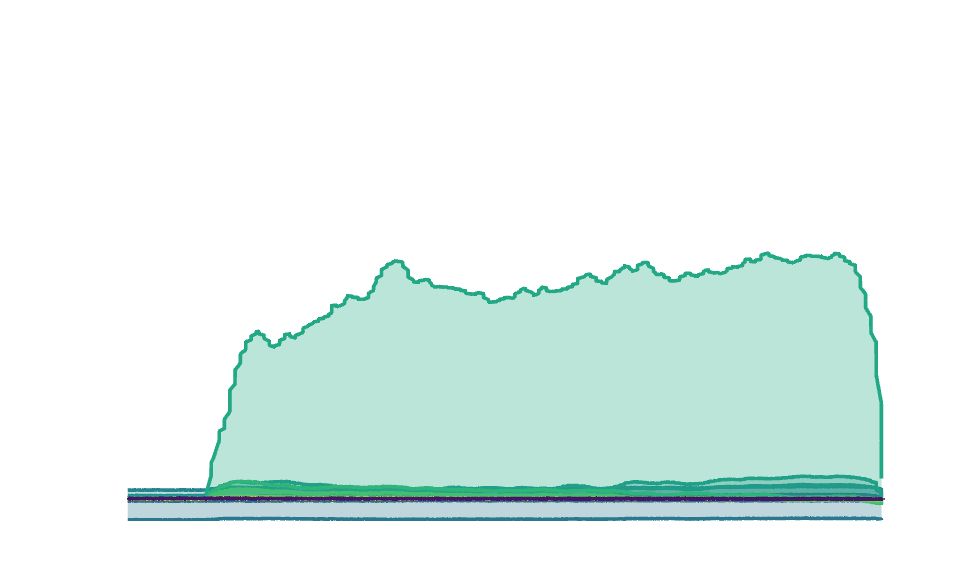

%plot and save the first of sensing interface
sub1=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
data=fbgs; hold on; grid on; box on;
n=21;
c=(slanCM('viridis',n));
for i=2:22
    x=data(:,1)-tmin;
    y=data(:,i);
    area(x,y,'FaceAlpha',0.3,'FaceColor',c(mod(i,n)+1,:)); 
    plot(x,y,'LineWidth',2,'Color',c(mod(i,n)+1,:));
    [val,ix]=max(y);
    % text(x(ix),val,sprintf('%d',i));
end
%legend()
xlim([0.5 5]); ylim([-0.02 0.41]);
set(gca,'Visible','off');
xlabel('t'); ylabel('\Delta\lambda'); hold off;

%export
% saveas(sub1,'subfigures/sub1.fig');
% exportgraphics(sub1, 'subfigures/sub1.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub1, 'subfigures/sub1.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## sub2

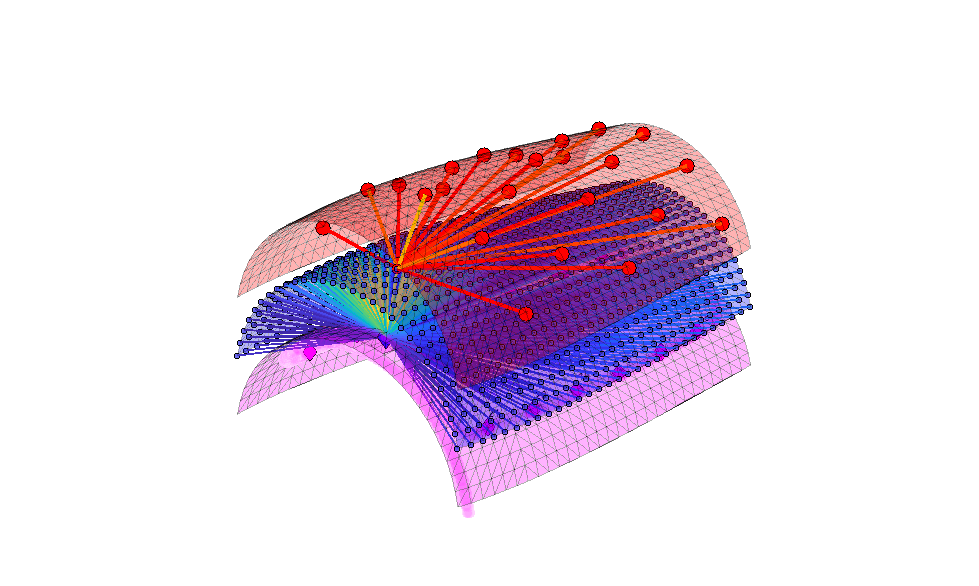

%load NN structure

%get sensorspositions
load sx.csv;
load sy.csv;
load sz.csv;

%get neuronspositions
load xc.csv
load yc.csv;
load zc.csv;
Tri = delaunay(xc,yc);

%get motorpositions
load xm.csv
load ym.csv;
load zm.csv;

%read stl of sensors line
importstl=stlread("path_fbg.stl");

%load deltas
load deltax.mat
load deltay.mat
load deltaz.mat

%compute lines
linex=-importstl.Points(:,1)+deltax;
liney=importstl.Points(:,3)+deltay;
linez=importstl.Points(:,2)+deltaz;

load Wh.csv
load Wh2.csv

strengths=rescale(Wh(11,:),1,900);
cmap=parula(900);

strengths2=rescale(Wh2(:,455),1,23);
cmap2=autumn(23);

sub2=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]); hold on;
delta=20;

%neurons
trisurf(Tri, xc, yc, zc,Wh(11,:),'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','b');
scatter3(xc,yc,zc,10,Wh(11,:),'filled','markerFaceAlpha',0.8,'MarkerEdgeColor','k'); colormap parula;
scatter3(xc(455),yc(455),zc(455),30,'r','filled','markerFaceAlpha',1,'MarkerEdgeColor','k');

%sensors
scatter3(linex,liney,linez-delta,30,"MarkerFaceColor",'m',"MarkerFaceAlpha",0.03,"MarkerEdgeColor","none");
trisurf(Tri, xc, yc, zc-delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','m');
scatter3(sx,sy,sz-delta,50,'dm','filled','markerFaceAlpha',1,'MarkerEdgeColor','k'); 
scatter3(sx(11),sy(11),sz(11)-delta,80,'db','filled','markerFaceAlpha',1,'MarkerEdgeColor','k'); 
for i=1:length(sx)
    text(sx(i),sy(i),sz(i)-delta+5,sprintf('%d',i),'Color','k','FontWeight','bold','FontSize',6);
end

%motors
scatter3(xm,ym,zm+delta,60,'or','filled','AlphaData',0.7,'MarkerEdgeColor','k');
trisurf(Tri, xc, yc, zc+delta,'EdgeAlpha',0.3,'EdgeColor','k','FaceAlpha',0.3,'Facecolor','r');

%lines
ref=[xc(455) yc(455) zc(455)];
for n=1:length(xm)
    pt=[xm(n) ym(n) zm(n)+delta];
    ix=floor(strengths2(n));
    xyz=vertcat(ref,pt);
    plot3(xyz(:,1),xyz(:,2),xyz(:,3),'LineWidth',2,'Color',cmap2(ix,:));
end

%lines
ref=[sx(11) sy(11) sz(11)-delta];
for n=1:length(xc)
    pt=[xc(n) yc(n) zc(n)];
    ix=floor(strengths(n));
    xyz=vertcat(ref,pt);
    plot3(xyz(:,1),xyz(:,2),xyz(:,3),'LineWidth',1,'Color',cmap(ix,:));
end
hold off; view(45,25); axis equal; axis off;

%export
% saveas(sub2,'subfigures/sub2.fig');
% exportgraphics(sub2, 'subfigures/sub2.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub2, 'subfigures/sub2.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## sub3

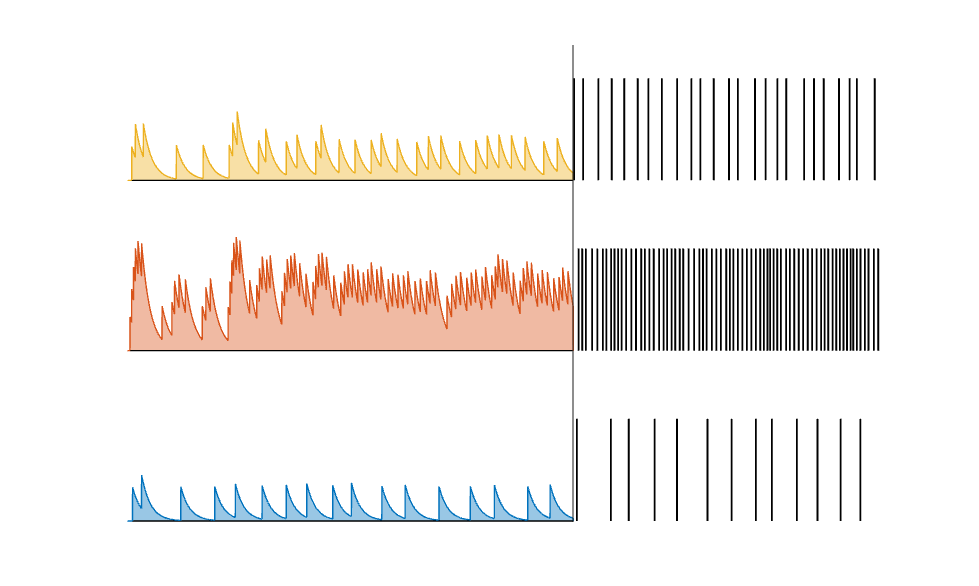

%timing issues
tc=0.0001; %s
tau=0.010; %s
g=1;
a=tc/(tau+tc);
T=1; %s
N=T/tc;
time=(1:tc:1+T)'; time(end)=[]; %ms

%create the 23 signals
ys=zeros(N,23);
for i=1:23

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=zeros(N,1);
    x=zeros(N,1);
    [~,closestIndex] = min(abs(time-spiketimes'));
    x(closestIndex)=1;

    %filtering operation
    for n=1:(N-1)    
        y(n+1)=g*a*x(n)+(1-a)*y(n);
    end
    y(1)=0; y(end)=0;
    
    %save the signal
    ys(:,i)=y;
end


sub3=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
vizscale=100;
hold on;
grid on; 

xtresh=1.5;
xline(xtresh);

%get the valid rows
valrows=find(sum(abs(ys)) ~= 0);
C=colororder;
% C=[0 0 0; C];
for j=1:length(valrows)

    %get the index
    i=valrows(j);
    
    %get the signal
    y=ys(:,i);

    %show
    ix=find(time<xtresh);
    tp=time(ix);
    yp=y(ix);
    yp(1)=0; yp(end)=0;
    fill(tp,vizscale*yp+i,0,'FaceColor',C(j,:),'FaceAlpha',0.4);
    plot(tp,vizscale*yp+i,'Color',C(j,:),'LineWidth',0.001);
end

yticks([valrows 23]);
xlim([1 1.85]);
axis off;



%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

% %plot all the spikes as lines
for i=1:length(ids)
    if allspikes(i)>xtresh
        line([allspikes(i) allspikes(i)], [ids(i) ids(i)+3],'Linewidth',1,'Color','k');
    end
end
hold off;  box off;

%export
% saveas(sub3,'subfigures/sub3.fig');
% exportgraphics(sub3, 'subfigures/sub3.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub3, 'subfigures/sub3.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## sub4

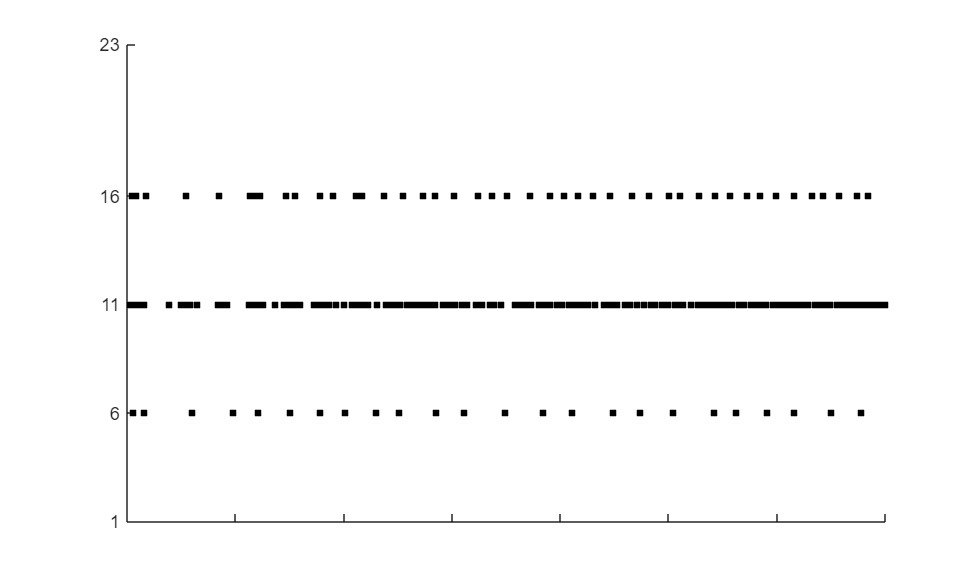

%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

sub4=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
hold on;
yticks([1 6 11 16 23])
ylim([1 23]);
xlim([1 1.7]);
xticklabels([]);
scatter(allspikes,ids,20,'s','filled','k');
hold off;


%export
% saveas(sub4,'subfigures/sub4.fig');
% exportgraphics(sub4, 'subfigures/sub4.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub4, 'subfigures/sub4.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## sub5

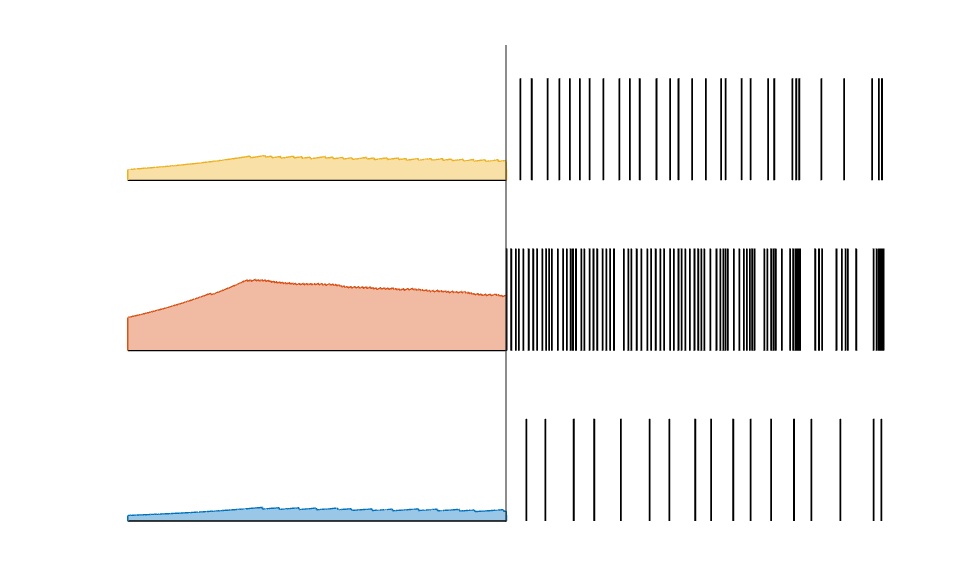

%the signals are the same of sub3, but redo the figure in specular way

%timing issues
tc=0.0001; %s
tau=0.010; %s
g=1;
a=0.0005;
T=1; %s
N=T/tc;
time=(1:tc:1+T)'; time(end)=[]; %ms

%create the 23 signals
ys=zeros(N,23);
for i=1:23

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=zeros(N,1);
    x=zeros(N,1);
    [~,closestIndex] = min(abs(time-spiketimes'));
    x(closestIndex)=1;

    %filtering operation
    for n=1:(N-1)    
        y(n+1)=g*a*x(n)+(1-a)*y(n);
    end
    y(1)=0; y(end)=0;
    
    %save the signal
    ys(:,i)=y;
end

sub5=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
vizscale=100;
hold on;
grid on; 

xtresh=1.5;
xline(xtresh);

%get the valid rows
valrows=find(sum(abs(ys)) ~= 0);
C=colororder;
% C=[0 0 0; C];
for j=1:length(valrows)

    %get the index
    i=valrows(j);
    
    %get the signal
    y=ys(:,i);

    %show
    ix=find(time>xtresh);
    tp=time(ix);
    yp=y(ix);
    yp(1)=0; yp(end)=0;
    fill(tp,vizscale*yp+i,0,'FaceColor',C(j,:),'FaceAlpha',0.4);
    plot(tp,vizscale*yp+i,'Color',C(j,:),'LineWidth',0.001);
end

yticks([valrows 23]);
% ylim([11 21]);
xlim([1 2]);
axis off;
set(gca,'XDir','reverse');

%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

% %plot all the spikes as lines
for i=1:length(ids)
    if allspikes(i)<xtresh
        line([allspikes(i) allspikes(i)], [ids(i) ids(i)+3],'Linewidth',1,'Color','k');
    end
end
hold off;  box off;

%export
% saveas(sub5,'subfigures/sub5.fig');
% exportgraphics(sub5, 'subfigures/sub5.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub5, 'subfigures/sub5.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Run simulink simulation

runsimulation=0;
if runsimulation
    data1=[time ys(:,6)*6500];
    data2=[time ys(:,11)*6500];
    data3=[time ys(:,16)*6500];
    
    %run simulink m8 for figure;
    out=sim("test_haptic_skin_scheduler_vtrial_m8_forfigure");

    % get signals
    t=out.tout;
    X=out.simout;

    %save the data
    save('t','t');
    save('X','X');
else
    load('t.mat');
    load('X.mat');
end

## sub6

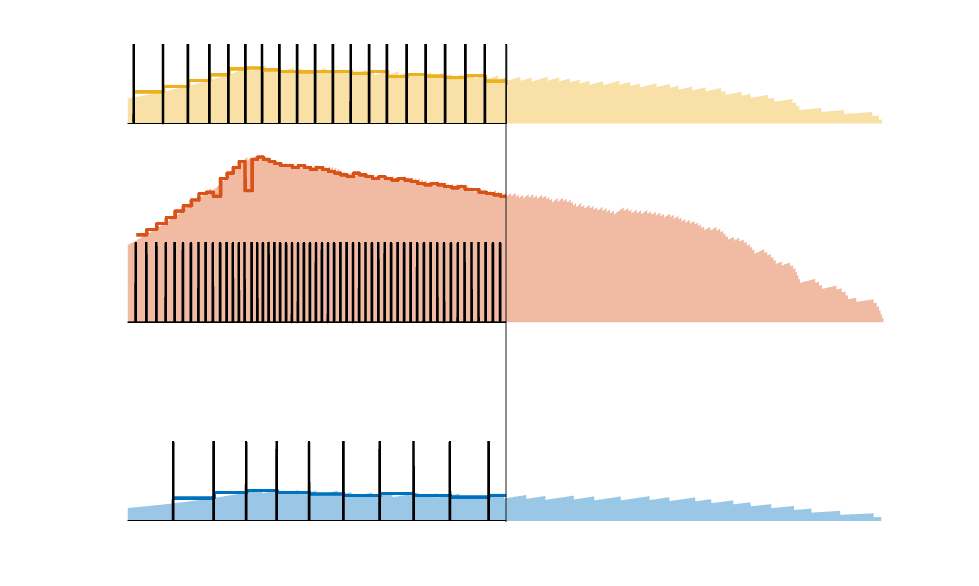

sub6=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
%
hold on;
visualizerscale=2;
xtresh=1.5;
xline(xtresh);
grid on; 

%recall the 23 signals
c=0;
for i=1:23 %4

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=ys(:,i);

    %result
    ix=time<xtresh;
    timep=time(ix);
    yp=y(ix);
    timep=time; yp=y;
    yp(1)=0; yp(end)=0;
    %fill(time(:),y(:),0,'FaceColor',C(i,:),'FaceAlpha',0.4);
    if any(y)
        % plot(time,y+i,'Color','r');
        c=c+1;
        fill(timep,visualizerscale*100*yp+i,0,'FaceColor',C(c,:),'FaceAlpha',0.4,'EdgeColor','none');
    end
end



set(gca, 'XDir','reverse');
% ylim([1 23]);
yticks([1 6 11 16 23]);

xlim([1 2]);
box on;
motorlines=[6 11 16];
%adjust time
td=t(1:end-1);

%get the rising edges of the pulses with a discrete I order derivative
Xd=X(2:end,:)-X(1:end-1,:);
Xd(Xd<=0)=0;
for i=1:size(X,2)
    
    %initialize freqs
    freqs=nan(size(td));
    
    %find the t of rising edges
    edges=td(Xd(:,i)==1);
    
    %find the deltat between adjacent t
    diffs=edges(2:end)-edges(1:end-1); 
    diffs=[diffs; 0];
    
    %istantaneous frequency 
    freqs(Xd(:,i)==1)=1./diffs;
    freqt=freqs(~isnan(freqs));
    freqsint=fillmissing(freqs,"previous");
    
    %report
    ix=td>xtresh;
    tdn=td(ix);
    freqsint=freqsint(ix);
    % freqsint(1)=0; freqsint(end)=0;
    plot(tdn,visualizerscale*freqsint*100/6500+motorlines(i),'LineWidth',2,'Color',C(i,:));  grid on;
end


ix=t>xtresh;
plot(t(ix),2*X(ix,1)+6,"Color",'k','LineWidth',1);
plot(t(ix),2*X(ix,2)+11,"Color",'k','LineWidth',1);
plot(t(ix),2*X(ix,3)+16,"Color",'k','LineWidth',1);
axis off;
hold off;


% export
% saveas(sub6,'subfigures/sub6.fig');
% exportgraphics(sub6, 'subfigures/sub6.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub6, 'subfigures/sub6.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## sub7

sub7=figure('Units','centimeters','Position',[3.5,1.7,20.9,12.5]);
mot=[6 11 16];
hold on;
for i=1:3
    plot(t,X(:,i)+mot(i),'LineWidth',2);
end
hold off;
xlim([1.55 2]);
yticks([1 6 11 16 23]);
set(gca,'XDir','reverse');
ylim([0 23]);
axis off;
% export
% saveas(sub7,'subfigures/sub7.fig');
% exportgraphics(sub7, 'subfigures/sub7.png', 'ContentType', 'image','Resolution',300);
% exportgraphics(sub7, 'subfigures/sub7.pdf', 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);